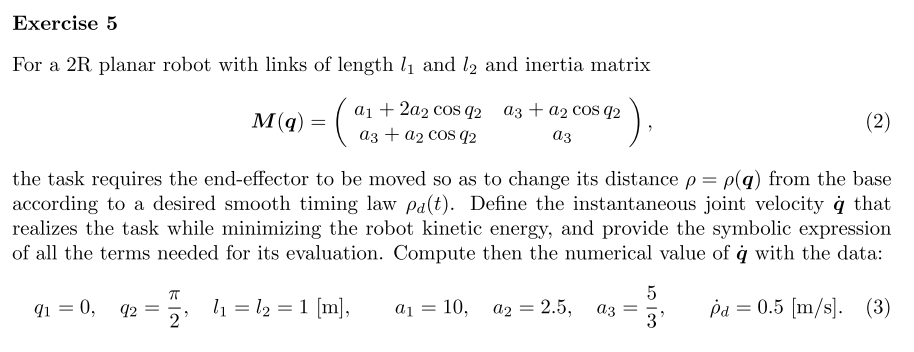

syms a1 a2 a3 q1 q2 l1 l2 rho_dot_des real

q=[q1 q2]';
r=[l1*cos(q1)+l2*cos(q1+q2);
   l1*sin(q1)+l2*sin(q1+q2)];

rho=sqrt(simplify(r'*r))

$$rho = \sqrt{{l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}}$$

rho_dot=-2*sin(q2)*l1*l2;
J=jacobian(rho, q);

M=[a1+2*a2*cos(q2)  a3+a2*cos(q2);
   a3+a2*cos(q2)    a3];

Minv=inv(M);

rho_dot_controllo=Minv*J'*inv(J*Minv*J')*(rho_dot_des)

$$rho\_dot\_controllo = \left(\begin{array}{c} \frac{{\dot{\rho }}_{\mathrm{des}}\,\left(a_{3}+a_{2}\,\cos\left(q_{2}\right)\right)\,\sqrt{{l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}}}{l_{1}\,l_{2}\,\sin\left(q_{2}\right)\,\left(a_{1}+2\,a_{2}\,\cos\left(q_{2}\right)\right)}\\ -\frac{{\dot{\rho }}_{\mathrm{des}}\,\sqrt{{l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}}}{l_{1}\,l_{2}\,\sin\left(q_{2}\right)} \end{array}\right)$$


vpa(subs(rho_dot_controllo, {q1, q2, l1, l2, a1, a2, a3, rho_dot_des},{0, pi/2, 1, 1, 10, 2.5,5/3, 0.5}),5)

$$ans = \left(\begin{array}{c} 0.11785\\ -0.70711 \end{array}\right)$$